%Load

n_runs = 1000;
lenLbl = [8, 16, 32, 64, 128] % input length

lenLbl =      8    16    32    64   128


concLbl = [200, 400, 600, 800, 1000, 1200, 1400, 1600, 1800, 2000] % initial concentration in M

concLbl =          200         400         600         800        1000        1200        1400        1600        1800        2000


rateDur = [1, 2, 3, 5, 10, 20, 30, 50, 100, 200, 300, 450, 600, 1200, 1800, 2700];
rate = 1./rateDur;

BER_8 = zeros(size(concLbl,2),size(rateDur,2));
BER_16 = zeros(size(concLbl,2),size(rateDur,2));
BER_32 = zeros(size(concLbl,2),size(rateDur,2));
BER_64 = zeros(size(concLbl,2),size(rateDur,2));
BER_128 = zeros(size(concLbl,2),size(rateDur,2));

for i = 1:1:size(concLbl,2)
    for j = 1:1:size(rateDur,2)
        BER_8(i,j) = getAvgBER(concLbl(i),8,rateDur(j),n_runs);
        BER_16(i,j) = getAvgBER(concLbl(i),16,rateDur(j),n_runs);
        BER_32(i,j) = getAvgBER(concLbl(i),32,rateDur(j),n_runs);
        BER_64(i,j) = getAvgBER(concLbl(i),64,rateDur(j),n_runs);
        BER_128(i,j) = getAvgBER(concLbl(i),128,rateDur(j),n_runs);
    end
end

%save("BERValues/BER_avg.mat","BER_8","BER_16","BER_32","BER_64","BER_128");
% save("BERValues/BER_high.mat","BER_8","BER_16","BER_32","BER_64","BER_128");

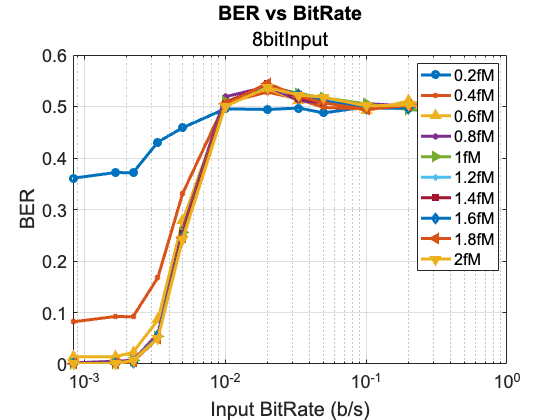

%Plot
figure(1)
% plot(rate(2:end-2),BER_all(1,2:end-2));
% hold on;
semilogx(rate(2:end-2),BER_8(1,2:end-2),'-o',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_8(2,2:end-2),'-x',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_8(3,2:end-2),'-^',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_8(4,2:end-2),'-*',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_8(5,2:end-2),'->',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(6,2:end-2),'-+',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(7,2:end-2),'-square',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(8,2:end-2),'-diamond',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(9,2:end-2),'-<',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_8(10,2:end-2),'-v',LineWidth=3);
grid on;
% ylim([0.35 0.55]);
% ylim([0 1]);
set(gca,'FontSize',18); set(gca,'FontName','Arial');
xlabel('Input BitRate (b/s)'), ylabel('BER');
legend("0.2fM","0.4fM","0.6fM","0.8fM","1fM","1.2fM","1.4fM","1.6fM","1.8fM","2fM")
title('BER vs BitRate','8bitInput');

% print ('BER19e-2_32_multi_75_new','-depsc');
% print ('BER19e-2_32_multi_75_new','-dpdf');
% print ('BER19e-2_32_multi_75_new','-dsvg');

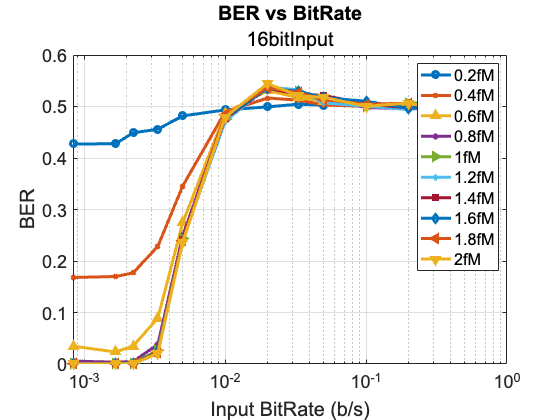

% 16 bit
figure(2)
% plot(rate(2:end-2),BER_all(1,2:end-2));
% hold on;
semilogx(rate(2:end-2),BER_16(1,2:end-2),'-o',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_16(2,2:end-2),'-x',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_16(3,2:end-2),'-^',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_16(4,2:end-2),'-*',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_16(5,2:end-2),'->',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_16(6,2:end-2),'-+',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_16(7,2:end-2),'-square',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_16(8,2:end-2),'-diamond',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_16(9,2:end-2),'-<',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_16(10,2:end-2),'-v',LineWidth=3);
grid on;
% ylim([0.35 0.55]);
% ylim([0 1]);
set(gca,'FontSize',18); set(gca,'FontName','Arial');
xlabel('Input BitRate (b/s)'), ylabel('BER');
legend("0.2fM","0.4fM","0.6fM","0.8fM","1fM","1.2fM","1.4fM","1.6fM","1.8fM","2fM")
title('BER vs BitRate','16bitInput');

% print ('BER19e-2_32_multi_75_new','-depsc');
% print ('BER19e-2_32_multi_75_new','-dpdf');
% print ('BER19e-2_32_multi_75_new','-dsvg');

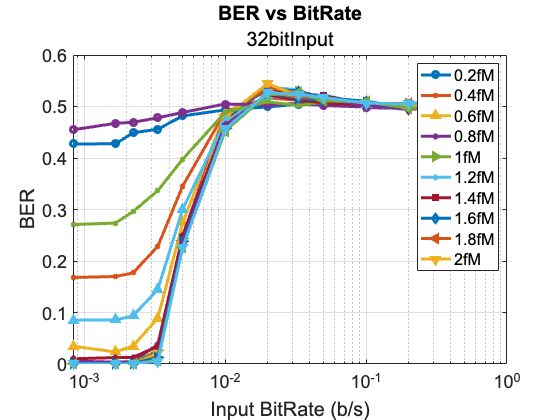

% 32 bit
figure(3)
% plot(rate(2:end-2),BER_all(1,2:end-2));
% hold on;
semilogx(rate(2:end-2),BER_32(1,2:end-2),'-o',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_32(2,2:end-2),'-x',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_32(3,2:end-2),'-^',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_32(4,2:end-2),'-*',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_32(5,2:end-2),'->',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_32(6,2:end-2),'-+',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_32(7,2:end-2),'-square',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_32(8,2:end-2),'-diamond',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_32(9,2:end-2),'-<',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_32(10,2:end-2),'-v',LineWidth=3);
grid on;
% ylim([0.35 0.55]);
% ylim([0 1]);
set(gca,'FontSize',18); set(gca,'FontName','Arial');
xlabel('Input BitRate (b/s)'), ylabel('BER');
legend("0.2fM","0.4fM","0.6fM","0.8fM","1fM","1.2fM","1.4fM","1.6fM","1.8fM","2fM")
title('BER vs BitRate','32bitInput');

% print ('BER19e-2_32_multi_75_new','-depsc');
% print ('BER19e-2_32_multi_75_new','-dpdf');
% print ('BER19e-2_32_multi_75_new','-dsvg');

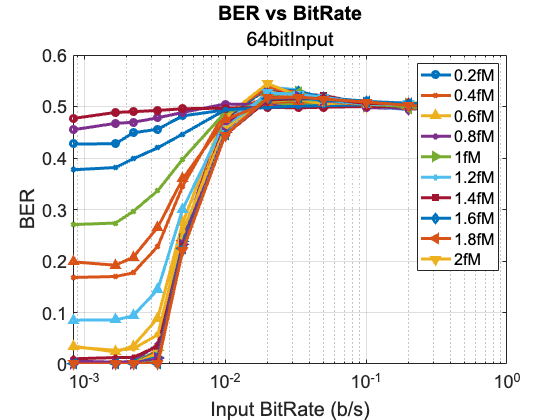

% 64 bit
figure(4)
% plot(rate(2:end-2),BER_all(1,2:end-2));
% hold on;
semilogx(rate(2:end-2),BER_64(1,2:end-2),'-o',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_64(2,2:end-2),'-x',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_64(3,2:end-2),'-^',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_64(4,2:end-2),'-*',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_64(5,2:end-2),'->',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_64(6,2:end-2),'-+',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_64(7,2:end-2),'-square',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_64(8,2:end-2),'-diamond',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_64(9,2:end-2),'-<',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_64(10,2:end-2),'-v',LineWidth=3);
grid on;
% ylim([0.35 0.55]);
% ylim([0 1]);
set(gca,'FontSize',18); set(gca,'FontName','Arial');
xlabel('Input BitRate (b/s)'), ylabel('BER');
legend("0.2fM","0.4fM","0.6fM","0.8fM","1fM","1.2fM","1.4fM","1.6fM","1.8fM","2fM")
title('BER vs BitRate','64bitInput');

% print ('BER19e-2_32_multi_75_new','-depsc');
% print ('BER19e-2_32_multi_75_new','-dpdf');
% print ('BER19e-2_32_multi_75_new','-dsvg');

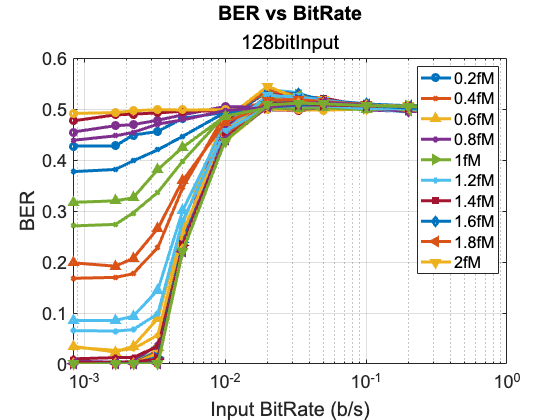

% 128 bit
figure(5)
% plot(rate(2:end-2),BER_all(1,2:end-2));
% hold on;
semilogx(rate(2:end-2),BER_128(1,2:end-2),'-o',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_128(2,2:end-2),'-x',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_128(3,2:end-2),'-^',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_128(4,2:end-2),'-*',LineWidth=3);
hold on;
semilogx(rate(2:end-2),BER_128(5,2:end-2),'->',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_128(6,2:end-2),'-+',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_128(7,2:end-2),'-square',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_128(8,2:end-2),'-diamond',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_128(9,2:end-2),'-<',LineWidth=3);
grid on;
semilogx(rate(2:end-2),BER_128(10,2:end-2),'-v',LineWidth=3);
grid on;
% ylim([0.35 0.55]);
% ylim([0 1]);
set(gca,'FontSize',18); set(gca,'FontName','Arial');
xlabel('Input BitRate (b/s)'), ylabel('BER');
legend("0.2fM","0.4fM","0.6fM","0.8fM","1fM","1.2fM","1.4fM","1.6fM","1.8fM","2fM")
title('BER vs BitRate','128bitInput');

% print ('BER19e-2_32_multi_75_new','-depsc');
% print ('BER19e-2_32_multi_75_new','-dpdf');
% print ('BER19e-2_32_multi_75_new','-dsvg');

function BER = getAvgBER(cc,len,dur,nRuns)
    C_O = load(strcat('ConcValues/runMulti5/C_O_',num2str(cc),'aM_multi',num2str(len),'_',num2str(dur),'_',num2str(75),'_runs',num2str(nRuns),'.mat')).C_O;
    x_in = load(strcat('ConcValues/runMulti5/x_in_',num2str(cc),'aM_multi',num2str(len),'_',num2str(dur),'_',num2str(75),'_runs',num2str(nRuns),'.mat')).x_in;
    bitSize = size(x_in,2);
    
    thresh1 = zeros(1,nRuns);
    for i=1:nRuns
        thresh1(1,i) = mean(C_O(:,i));
    end
    x_out1 = zeros(nRuns,bitSize);
    for i=1:nRuns
        for j=1:bitSize
            if(C_O(j,i)>thresh1(1,i))
                x_out1(i,j) = 1;
            end
        end
    end
    
    
    be1 = zeros(nRuns,bitSize);
    bec1 = zeros(nRuns,1);
    ber1 = zeros(nRuns,1);
    
    
    for i=1:nRuns
        be1(i,:) = xor(x_in(i,:),x_out1(i,:));
        bec1(i,1) = sum(be1(i,:)==1);
        ber1(i,1) = bec1(i,1)/bitSize;
    end
    
    AvgBER = mean(ber1);
    %HighBER = max(ber1); %very erratic

    BER = AvgBER;
end